# Cruise control: digital control

## System parameter

m = 1000;
b = 50;
s = tf('s');
sys = 1/(m*s +b);
Ts = 1/50;
sysd = c2d(sys, Ts, 'zoh');

## Design criteria

- Rise time < 5 s

- Overshoot < 10%

- Steady-state error < 2%

## Design

Based on the above requirement, the zeta = 0.6, omega = 0.36 rad/sec. But in digital control, zgrid require the omega in rad/sample.

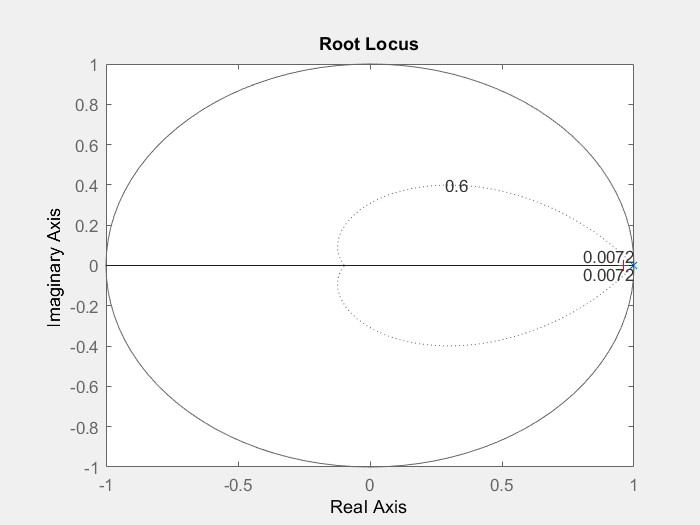

Select a point in the graphics window


selected_point = 0.9602 - 0.0099i

zeta = 0.6;
Wn = 0.36 * Ts;
rlocus(sysd);
zgrid(zeta, Wn);
axis([-1 1 -1 1]);
[k, poles] = rlocfind(sysd);

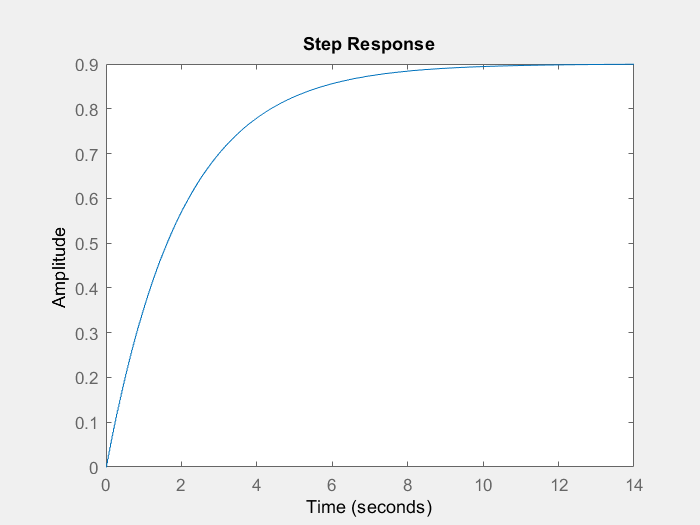

K = 451;
sysd_cl = feedback(K*sysd, 1);
step(sysd_cl);

The steady state error is not ok, so we need to change the controller.

## Lag compensator design

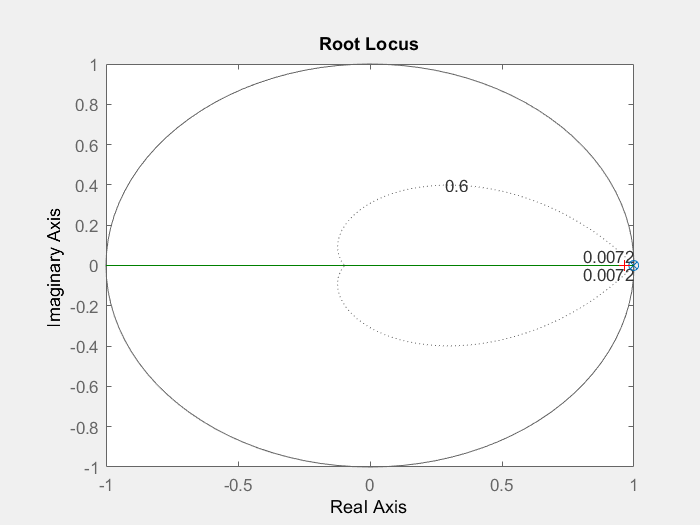

Select a point in the graphics window


selected_point = 0.9640

k = 1.7501e+03

poles = 0.9640

z = tf('z',Ts);
C = 0.2*(z - 0.999)/(z - 0.9998);
rlocus(C*sysd);
zgrid(zeta, Wn);
axis([-1 1 -1 1]);
[k, poles] = rlocfind(sysd)

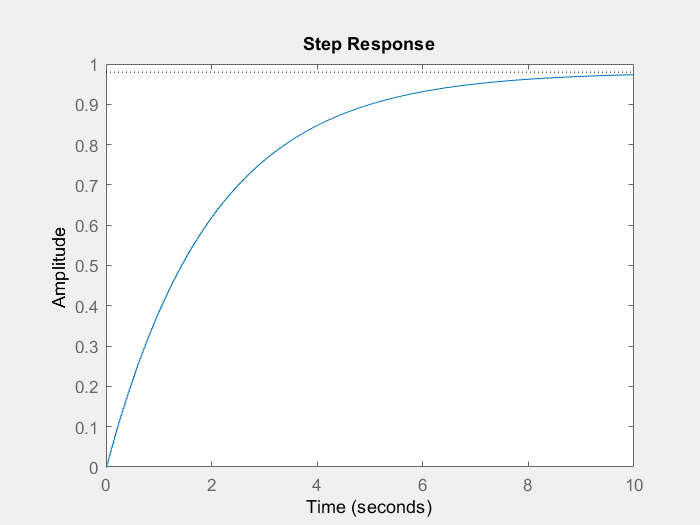

K = 2.4454e+03; % two poles at 0.99
sys_cl = feedback(K*C*sysd,1);
step(sys_cl,10);